# Simulación de la espira y campo magnético

clear; close all; clc;clearvars;

Parametros de la rejilla

x0 = -5;
x1 = 5;
xn = .5;
y0 = 0;
y1 = 0;
yn = .1;
z0 = x0;
z1 = x1;
zn = xn;

[xGrid,yGrid,zGrid] = meshgrid(x0:xn:x1,y0:yn:y1,z0:zn:z1);

Parametros de la espira

rCirculo = 2;
xn = .1;
xCirculo = -rCirculo:xn:rCirculo;
yCirculo = sqrt((rCirculo.^2)-xCirculo.^2);
zCirculo = zeros(size(xCirculo));

xn = xn/4;
rCirculo2 = .5;
xCirculo2 = -rCirculo2:xn:rCirculo2;
yCirculo2 = sqrt((rCirculo2.^2)-xCirculo2.^2);
zCirculo2 = zCirculo + 5;

datos B

u0 = 4.*pi.*10.^-7;
I = 30;

x = -2;
y = 0;
z = 0;

x2 = 2;
y2 = 0;
z2 = 0;

dx = (xGrid -x);
dy = (yGrid -y);
dz = (zGrid -z);
r1 = sqrt(dx.^2 + dy.^2 + dz.^2);

dx2 = (xGrid -x2);
dy2 = (yGrid -y2);
r2 = sqrt(dx2.^2 + dy2.^2 + dz.^2);

Bx = ((u0.*-I) .* (zGrid -z)) ./ (2.*r1.^2);
Bz = ((u0.*I) .* (xGrid -x)) ./ (2.*r1.^2);
By = Bx * 0;


Bx = Bx + ((u0.*I) .* (zGrid -z2)) ./ (2.*r2.^2);
Bz = Bz + ((u0.*-I) .* (xGrid -x2)) ./ (2.*r2.^2);


B = sqrt(Bx.^2+By.^2+Bz.^2);

Cx = Bx;
Cy = By;
Cz = Bz;

Graficas de velocidad y posición del imán en caida libre

vi = 0;
ac = 9.81;
zi = 5;
t = 0:.1:1;
yg = t .* 0;

vf = vi + ac.*t;
zf = zi + vi.*t + (1/2).*(-1*ac).*t.^2;


Graficamos 

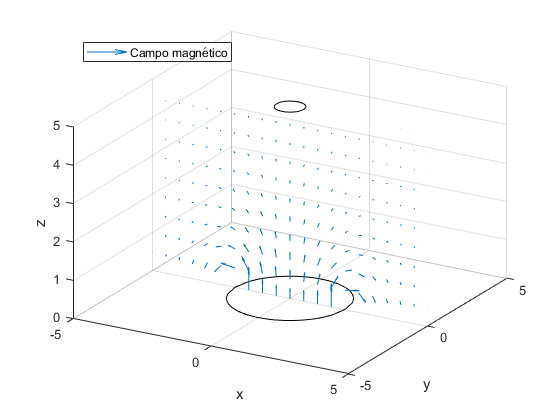

figure();
hold on;
axis([ -5 5 -5 5 0 5]);
xlabel("x"); ylabel("y");zlabel("z");
view(30,30);

quiver3(xGrid,yGrid,zGrid,Cx,Cy,Cz,'DisplayName',"Campo magnético");
plot3(xCirculo,yCirculo,zCirculo,'k',xCirculo,-yCirculo,zCirculo,'k');
plot3(xCirculo2,yCirculo2,zCirculo2,'k',xCirculo2,-yCirculo2,zCirculo2,'k');

grid on;
legend({'Campo magnético'},'AutoUpdate','off',"Location", "northwest");
hold off;

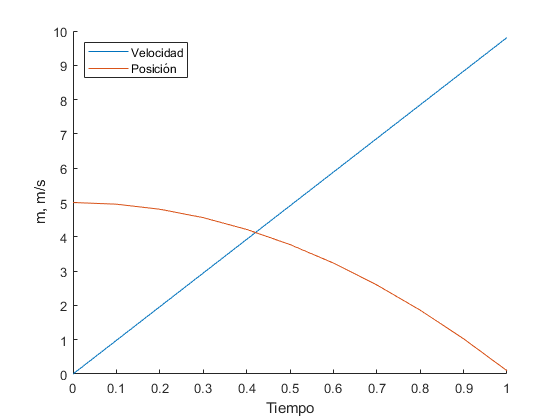


figure();
hold on;
plot(t,vf,'DisplayName',"Velocidad");
plot(t,zf,'DisplayName',"Posición");
legend("Location", "northwest")
xlabel("Tiempo"); ylabel("m, m/s");
hold off;

Graficas  Iniciales

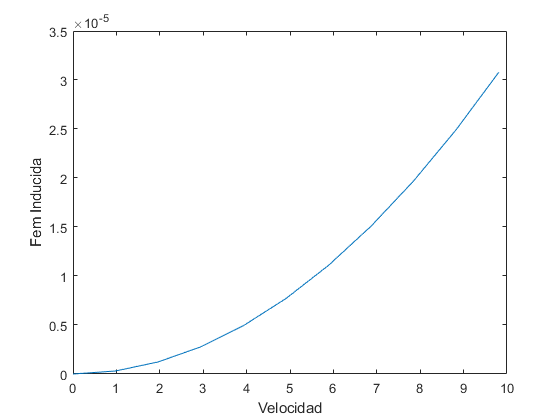

R = 2;
a = rCirculo;
r = sqrt(a^2+5^2);
A = a^2 * pi;
z = 0:zn:5;
g = -9.81;

fem = ((3.*u0.*I.*(a.^4).*pi.*z)/(2*r.^5)).*vf;

I = fem/R;

figure();
plot(vf,fem);
xlabel("Velocidad"); ylabel("Fem Inducida");

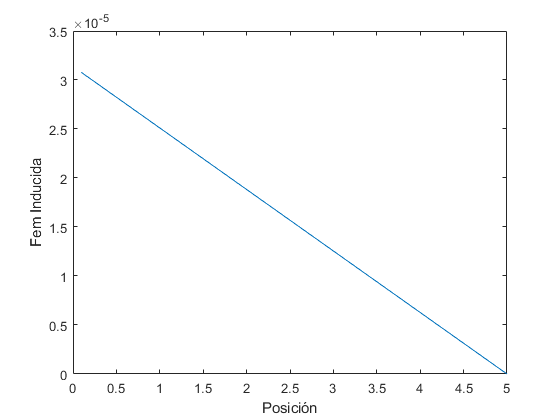


figure();
plot(zf,fem);
xlabel("Posición"); ylabel("Fem Inducida");

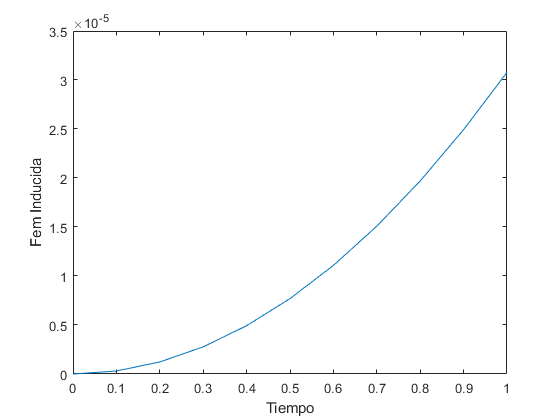


figure()
plot(t,fem);
xlabel("Tiempo"); ylabel("Fem Inducida");

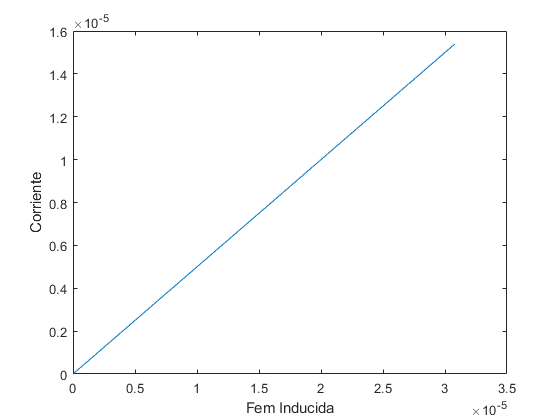


figure()
plot(fem,I);
xlabel("Fem Inducida"); ylabel("Corriente");


$$\frac{\mathrm{dv}}{\mathrm{dt}}=-g+\frac{27z^3 A\mu_0^3 u^2 a^6 {v_z }^2 }{8{\mathrm{mR}}^2 {\left(z^2 +a^2 \right)}^{\frac{15}{2}} }$$



$$\frac{\mathrm{dx}}{\mathrm{dt}}=v$$



$$I=\frac{3\mu_0 \mu a^2 {\mathrm{zv}}_z }{2{\left(a^2 +x^2 \right)}^{\frac{5}{2}} R}\;$$


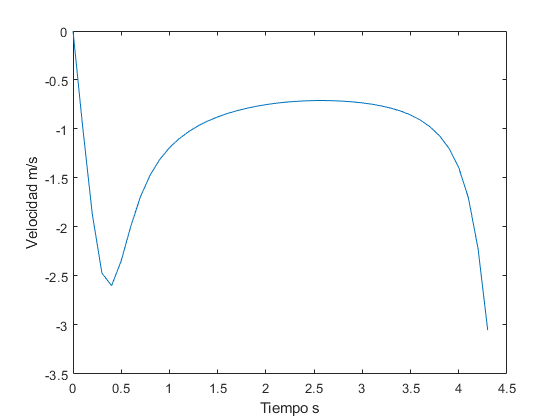

z0 = 5;
v0 = 0;

a = 1;
r = sqrt(a^2+z0^2);
A = r^2 * pi;
S = pi*a^2;
g = 9.81;
m = 0.01;
dt =0.1;
u0 = 4.*pi.*10.^-7;
u = 1000000;
R = 0.00009;

f = @(z,v,t) -g + ((27*(z^3)*A*(u0^3)*(u^2)*(r^6)*(v^2))/(8*m*(R^2)*(z^2+r^2)^(15/2)))*t;
g = @(v) v;

a0 = f(z0,v0,0);

t = 0:0.1:4.3;
z = zeros(1,length(t));
pos = z;

pos(1) = z0;

[z,v,ac,t]=RK4(f,g,pos,v0,a0);

I = ((3.*u0.*u.*r.^2.*z)/(2.*(a.^2+r.^2).^5/2 .* R)).*v;

figure();
plot(t,v);
xlabel("Tiempo s"); ylabel("Velocidad m/s")

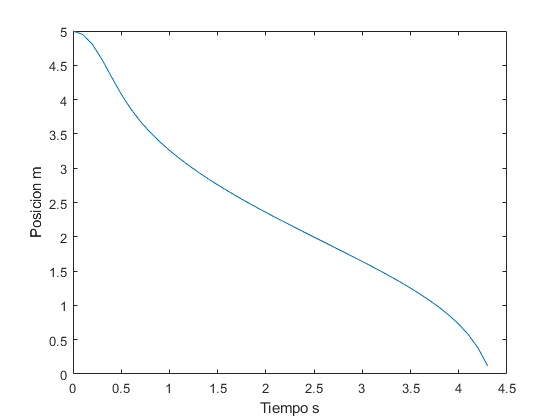



figure()
plot(t,z);
xlabel("Tiempo s"); ylabel("Posicion m");

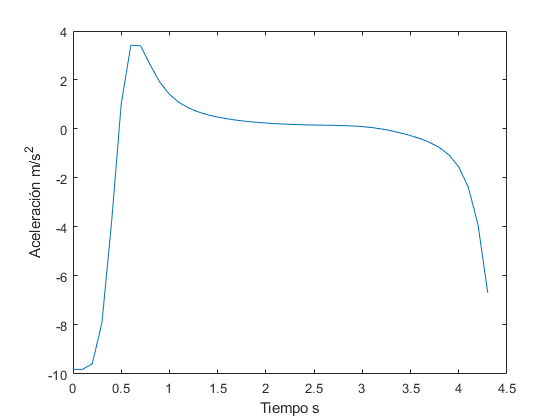

figure()
plot(t,ac);
xlabel("Tiempo s"); ylabel("Aceleración m/s^2");

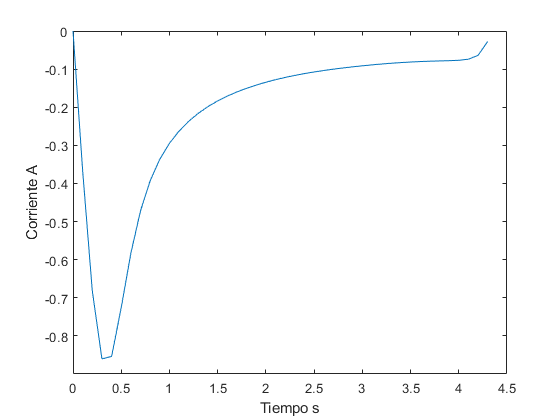



figure()
plot(t,I);
xlabel("Tiempo s"); ylabel("Corriente A");

Metodo Runge kutta 4to orden

function [z,v,a,t] = RK4(f,g,z2,vi,ai)
    z = z2;
    a = zeros(1,length(z));
    v = zeros(1,length(z));
    t = zeros(1,length(z));
    v(1) = vi;
    a(1) = ai;
    t(1) = 0;
    
    h = 0.1;
    dt = 0.1;

    for i = 1:(length(z)-1)       
        l1 = h*f(z(i),v(i),t(i));
        k1 = h*g(v(i));
        l2 = h*f(z(i)+0.5*k1,v(i)+.5*l1,t(i)+0.5*h);
        k2 = h*g(v(i)+0.5*l1);
        l3 = h*f(z(i)+0.5*k2,v(i)+.5*l2,t(i)+0.5*h);
        k3 = h*g(v(i)+0.5*l2);
        l4 = h*f(z(i)+k3,v(i)+l3,t(i)+h);
        k4 = h*g(v(i)+l3);
        
        v(i+1) = v(i)+ (1/6)*(l1+(2*l2)+(2*l3)+l4);
        z(i+1) = z(i)+ (1/6)*(k1+(2*k2)+(2*k3)+k4);
        t(i+1) = t(i) + dt;
        a(i+1) = f(z(i),v(i),t(i));
    end
end
